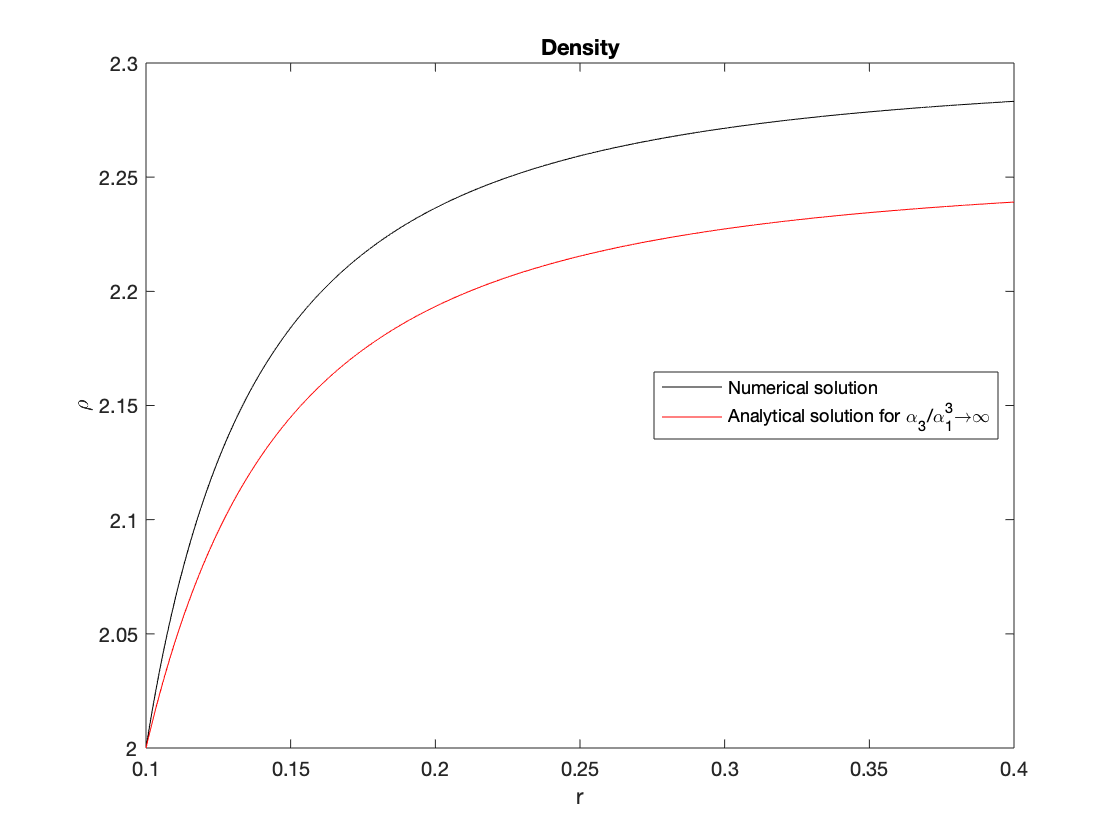

% Initialization
close all
clear
clc

% Parameters
gamma=1.4;

% Grid
nr=10000;
r=linspace(0.1,0.4,nr+1)';

% Inlet values
rI=r(1);
rhoI=2;
urI=200;
pI=2e5;

% Numerical solution
alpha1=rI*rhoI*urI;
alpha2=0;
alpha3=rI*urI*(gamma/(gamma-1)*pI+1/2*rhoI*urI^2);
drho_dr=@(r,rho) rho/((alpha3/alpha1^3*rho^2*r^2-(gamma+1)/(2*(gamma-1)))*(gamma-1)*r);
[~,rho]=ode45(drho_dr,r,rhoI);
ur=alpha1./(r.*rho);
p=(gamma-1)/gamma*(alpha3./(r.*ur)-1/2*rho.*ur.^2);

% Analytical solution for alpha3/alpha1^3->Inf
rho_Inf=sqrt(rhoI^2+alpha1^3/(alpha3*(gamma-1))*(1/r(1)^2-1./r.^2));
ur_Inf=alpha1./(rho_Inf.*r);
p_Inf=(gamma-1)/gamma*(alpha3./(r.*ur)-1/2*rho.*ur.^2);

% Plot solution of density
figure
plot(r,rho,'k')
hold on
plot(r,rho_Inf,'r')
xlim(minmax(r'))
xlabel('r')
ylabel('\rho')
legend('Numerical solution','Analytical solution for \alpha_3/\alpha_1^3\rightarrow\infty','Location','East')
title('Density')

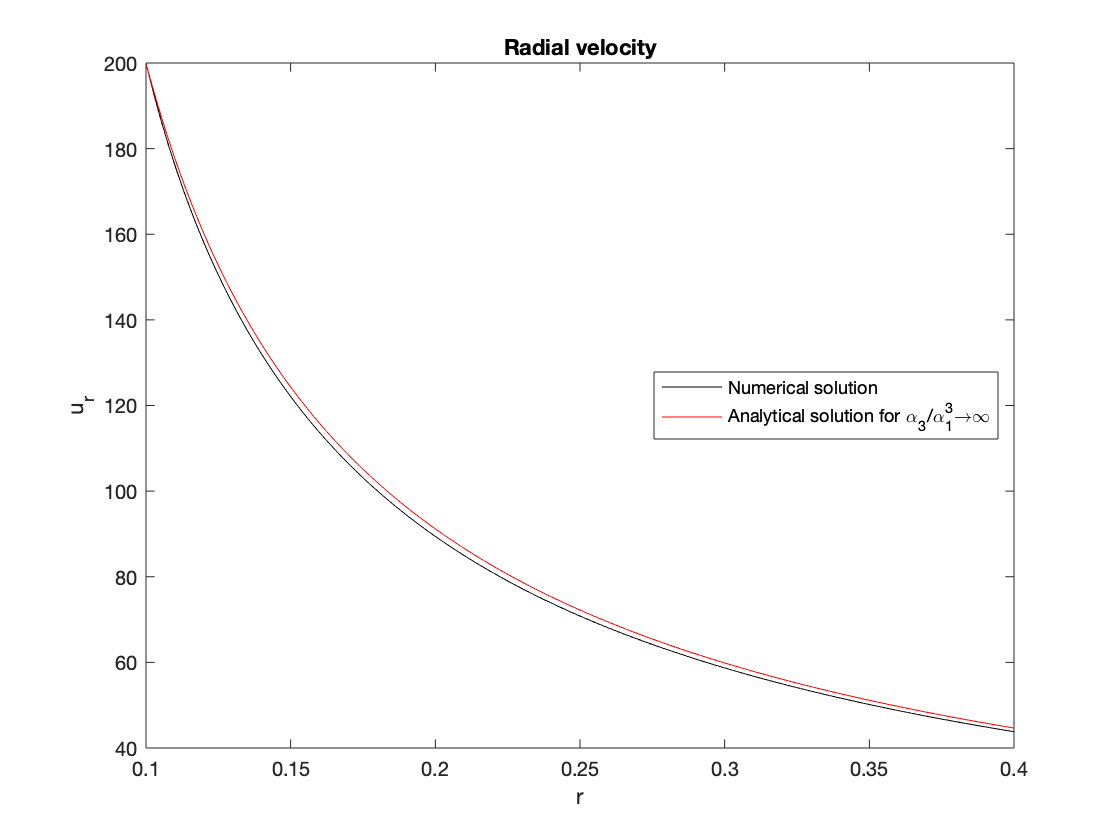


% Plot solution of radial velocity
figure
plot(r,ur,'k')
hold on
plot(r,ur_Inf,'r')
xlim(minmax(r'))
xlabel('r')
ylabel('u_r')
legend('Numerical solution','Analytical solution for \alpha_3/\alpha_1^3\rightarrow\infty','Location','East')
title('Radial velocity')

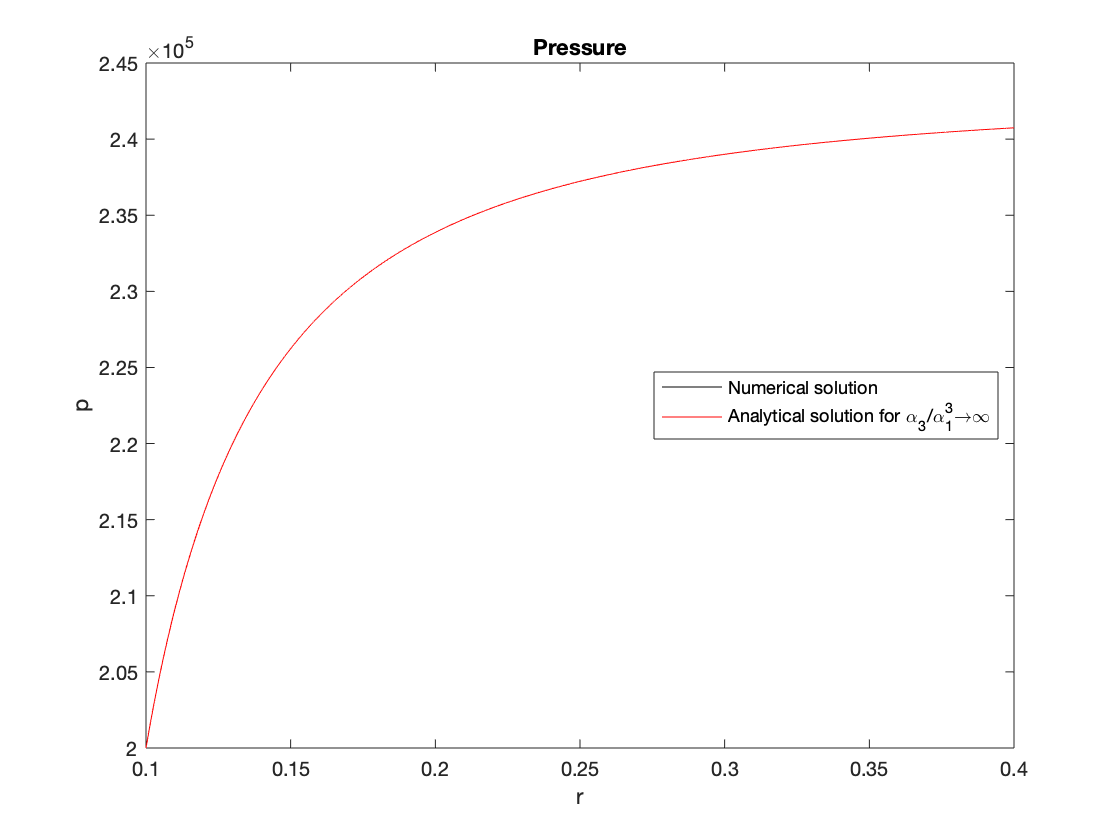


% Plot solution of pressure
figure
plot(r,p,'k')
hold on
plot(r,p_Inf,'r')
xlim(minmax(r'))
xlabel('r')
ylabel('p')
legend('Numerical solution','Analytical solution for \alpha_3/\alpha_1^3\rightarrow\infty','Location','East')
title('Pressure')


% Print boundary values
fprintf('Inlet \t\t Outlet')

Inlet 		 Outlet

fprintf('rho = %.0f \t %.6f',rho(1),rho(end))

rho = 2 	 2.283213

fprintf('ur  = %.0f \t %.6f',ur(1),ur(end))

ur  = 200 	 43.797935

fprintf('p   = %.0e \t %.6e',p(1),p(end))

p   = 2e+05 	 2.407425e+05